# LQR Aircraft Pitch Control

This example deals with the problem of aircraft pitch control. It is inspired by the University of Michigan Control Tutorials for MATLAB & Simulink. 

## System Modeling

The aircraft pitch equations take the form: 


$$\left[\begin{array}{|c|} \dot\alpha \\ \dot q \\ \dot \theta \end{array}\right] = \left[\begin{array}{c}{-0.313 & 56.7 & 0 \\-0.0139 & -0.426 & 0 \\ 0 & 56.7 &0 \end{array}\right] \left[\begin{array}{c} a \\ q \\ \theta \end{array}\right] + \left[\begin{array}{c} 0.232 \\ 0.0203 \\ 0\end{array} \right] \delta$$


and


$$y = \left[ \begin{array}{c} 0 & 0 & 1\end{array}\right] \left[ \begin{array}{c} a \\ q \\ \theta\end{array} \right]$$


## Verify Controllability

In order to be able to design a controller, the controllability of the abovementioned state space representation has to be verified. For Linear Time Invariant systems such as the one above, this means that the matrix: 


$$C = [B|AB|\cdots|A^{n-1}B]$$


has to be full rank. We do so using the following:

A = [-0.313 56.7 0; -0.0139 -0.426 0; 0 56.7 0];
B = [0.232; 0.0203; 0];
C = [0 0 1];
D = [0];

co = ctrb(A,B);

Controllability = rank(co)

Which verifies that the system is controllable.

## Linear Quadratic Regulator synthesis

We will use a technique called the **Linear Quadratic Regulator (LQR)** method to generate the "best" gain matrix *K*, without explicitly choosing to place the closed-loop poles in particular locations. This type of control technique optimally balances the system error and the control effort based on a cost that the designer specifies that defines the relative importance of minimizing errors and minimimizing control effort. In the case of the regulator problem, it is assumed that the reference is zero. Therefore, in this case the magnitude of the error is equal to the magnitude of the state. To use this LQR method, we need to define two parameters: the state-cost weighted matrix (*Q*) and the control weighted matrix (*R*). For simplicity, we will choose the control weighted matrix equal to 1 (*R*=1), and the state-cost matrix (*Q*) equal to *pC'C*. Employing the vector *C* from the output equation means that we will only consider those states in the output in defining our cost. 

p = 2;
Q = p*C'*C
R = 1;
[K] = lqr(A,B,Q,R)

We then generate the closed loop system using the following commands:

sys_cl = ss(A-B*K, B, C, D);
step(0.2*sys_cl)
ylabel('pitch angle (rad)');
title('Closed-Loop Step Response: LQR');

Examination of the above demonstrates that the response is too slow. We can tune the performance of our system to be faster by weighting the importance of the error more heavily than the importance of the control effort. More specifically, this can be done by increasing the weighting factor *p*. After some trial and error, we settle on a value of *p* = 50. Modify the code of your m-file as follows and then run at the command line to produce the following step response.

p = 50;
Q = p*C'*C;
R = 1;
[K] = lqr(A,B,Q,R)
sys_cl = ss(A-B*K, B, C, D);
step(0.2*sys_cl)
ylabel('pitch angle (rad)');
title('Closed-Loop Step Response: LQR');

Examination of the above demonstrates that the rise time, overshoot, and settling time are satisfactory. However, there is a large steady-state error. One way to correct this is by introducing a precompensator (*Nbar*) to scale the overall output.

## Adding precompensation

Unlike other design methods, the full-state feedback system does not compare the output to the reference; instead, it compares all states multiplied by the control matrix (*K* **x**) to the reference (see the schematic shown above). Thus, we should not expect the output to equal the commanded reference. To obtain the desired output, we can scale the reference input so that the output does equal the reference in steady state. This can be done by introducing a precompensator scaling factor called *Nbar*. The basic schematic of our state-feedback system with scaling factor (*Nbar*) is shown below.

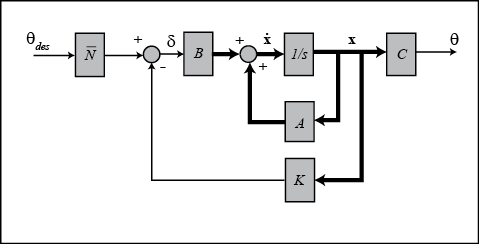

We can easily find *Nbar* from the MATLAB function [rscale.m](http://ctms.engin.umich.edu/CTMS/index.php?aux=Extras_rscale). Since `rscale.m` is a user-defined function, you need to copy and save the function to your directory. For further assistance in using user-defined functions, refer to the [function](http://ctms.engin.umich.edu/CTMS/index.php?aux=Extras_Function) page. After you have saved the `rscale.m` file to your directory, modify the code of your m-file as follows and run it in the MATLAB command window.

p = 50;
Q = p*C'*C;
R = 1;
[K] = lqr(A,B,Q,R);
Nbar = rscale(A,B,C,D,K)

Adding the following code and rerunning your m-file will then generate the response shown below.

sys_cl = ss(A-B*K,B*Nbar,C,D);
step(0.2*sys_cl)
ylabel('pitch angle (rad)');
title('Closed-Loop Step Response: LQR with Precompensation');

Now the steady-state error has been eliminated and all design requirements are satisfied.